% Example 3.4 from Murray Lectures

% Properties of dynamical system
A = [0 1; 0 0];
B = [0;1];
[n,~] = size(A);

% Penaliza
q = 2;
Qx = [q^2 0; 0 0];
Qu = 1;

% Function
ft = @(t,x,u) A*x + B*u;

% Setting of numerical solver
tf = 10;
dt= 0.1;
time = 0:dt:tf; 
options = odeset('RelTol',1e-13,'AbsTol',1e-300);
P0 = reshape(eye(n),n*n,1);
[tspan, P_i] = ode45(@(t,P)riccati(t,P,A,B,Qu,Qx,n),time, P0, options);

%Runge-Kutta 4
k1 = @(t,x,u) (  ft(t,x,u) );
k2 = @(t,x,u) ( ft(t,x + k1(t,x,u)*dt/2,u) );
k3 = @(t,x,u) ( ft(t,x + k2(t,x,u)*dt/2,u) );
k4 = @(t,x,u) ( ft(t,x + k1(t,x,u)*dt,u) );
f_ud = @(t,x,u) ( x + (dt/6) * ( k1(t,x,u) + 2*k2(t,x,u) + 2*k3(t,x,u) + k4(t,x,u)  )   );
%
x0 =[-1;1];
xOL = zeros(n,length(tspan));
xOL(:,1) = x0;
xCL = zeros(n,length(tspan));
xCL(:,1) = x0;
for i = 1:length(tspan)-1
    xOL(:,i+1) = f_ud(0,xOL(:,i),0);  %open loop
    u = -(Qu\B')*reshape(P_i(i,:),n,n)*xCL(:,i);  % u=
    xCL(:,i+1) = f_ud(0,xCL(:,i),u);
end

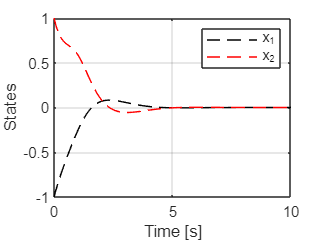

figure(1);
plot(time,xCL(1,:),"--k", "DisplayName","x_1")
hold on;
plot(time,xCL(2,:),"--r", "DisplayName","x_2")
legend
xlabel("Time [s]")
ylabel("States")
grid on;

function dPdt=riccati(~,P,A,B,Qu,Qx,n)
    P = reshape(P,n,n);
    dPdt = P*A + A'*P - P*B*(Qu\B')*P + Qx;
    dPdt = reshape(dPdt,n*n,1);
end